**Task 2: Numerical approximations of **$\mathbb{E}[Q(u)]$

`1.Richardson Extrapolation`

We want to estimate the bias, i.e.

                        
$$Q(u_h)-Q(u) = a_1h^p + \mathcal{O}(h^r)$$


for some $r>p$. Using Richardson extrapolation, we can obtain an approximation of the bias that is $r^{\text{th}}$-order accurate. For example

            (I)     $Q(u_h) - Q(u) = a_1h^p + a_2h^r+\text{h.o.t.}$

           (II)     $Q(u_{h/2}) - Q(u) = \frac{a_1}{2^p}h^p +  \frac{a_2}{2^p}h^r+\text{h.o.t.}$

Subtracting (II) from (I) yields

                
$$Q(u_h) - Q(u_{h/2})= \left(1-\frac{1}{2^p}\right)a_1h^p + \mathcal{O}(h^r)$$


such that the bias is approximately

                
$$\text{Bias} = Q(u_h)- Q(u) \approx \frac{1}{\left(1 - \frac{1}{2^p}\right)}\left(Q(u_h)- Q(u_{h/2})\right)$$


For an estimation of $p$ we compute $\mathbb{E}[Q(u_h) - Q(u)]$ for a range of $I$'s for a constant sample size of $M=10^3$

N = 20; % Mesh for RF discretization
M = 10^2; % Number of samples
I = 128; % Only 64 since we take 2*I for bias estimation
start_index = 10;
samples_h = zeros([M I-start_index+1]);
samples_h2 = zeros([M I-start_index+1]);
Est_h = zeros([1 I-start_index+1]);
Est_h2 = zeros([1 I-start_index+1]);
err = zeros([1 I-start_index+1]);

for k=progress(1:M)
    for i=start_index:I
        samples_h(k, i-start_index+1) = QoI_parameter(I, 1, 0.1, N);
        samples_h2(k, i-start_index+1) = QoI_parameter(2*I, 1, 0.1, N);
    end
end

Processing:  000%  |                                      | 0/100it [00:00:00<Inf:NaN:NaN, Inf it/s]


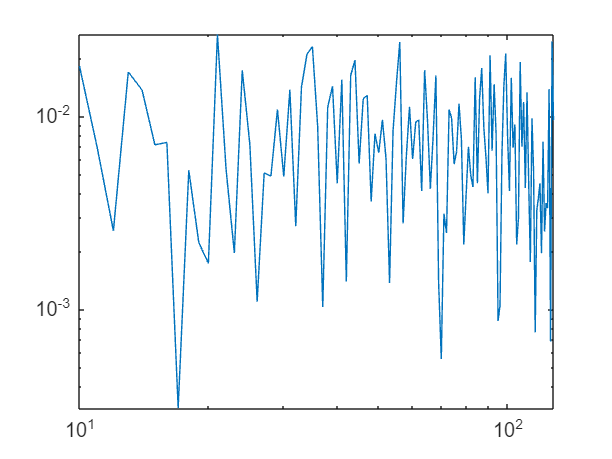


for i=start_index:I
    Est_h(i-start_index+1) = 1/M*sum(samples_h(:, i-start_index+1));
    Est_h2(i-start_index+1) = 1/M*sum(samples_h2(:, i-start_index+1));
    err(i-start_index+1) = abs(Est_h(i-start_index+1) - Est_h2(i-start_index+1))/abs(Est_h2(i-start_index+1));
end

loglog(start_index:I, err)